# Use PDE Toolbox to generate a reduced order model

Copyright 2021 - 2022 The MathWorks, Inc.

The [Reduced Order Flexible Solid](https://www.mathworks.com/help/physmod/sm/ref/reducedorderflexiblesolid.html) block models a deformable body based on a reduced-order model that characterizes the geometric and mechanical properties of the body. The basic data imported from the reduced-order model includes:

- A list of coordinate triples that specify the position of all interface frame origins relative to a common reference frame.

- A symmetric stiffness matrix that describes the elastic properties of the flexible body.

- A symmetric mass matrix that describes the inertial properties of the flexible body.

There are several ways to generate the reduced-order data required by this block. Typically, you generate a substructure (or superelement) by using finite-element analysis (FEA) tools.

This script uses the Partial Differential Equation Toolbox™ to create a reduced-order model for a cylinder with these properties:

- Radius: r = 0.05 m

- Length: L = 1 m

- Density: rho = 2700 kg/m^3

- Youngs Modulus: 70 GPa

- Poisson ratio: 0.33

- 2 interface frames (one at each end)

You start with the CAD geometry of the cylinder, generate a finite-element mesh, apply the [Craig-Bampton](https://hal.archives-ouvertes.fr/hal-01537654/file/RCMB.pdf) FEA substructuring method, and generate a reduced-order model. You can then use the generated reduced-order model in [`compareFlexibleCylinders`](matlab:compareFlexibleCylinders). The workflow in this live script is similar to the [Flexible Dipper Arm](https://www.mathworks.com/help/releases/R2020b/physmod/sm/ug/model-excavator-dipper-arm.html) example.

if(license('checkout','PDE_Toolbox')==0)
    error("You need PDE Toolbox to run this script");
end

## Step 1: Define the Geometry and Material Properties of the Cylinder

The file `Cylinder.STL` contains a triangulation that defines the CAD geometry of the component. To view the geometry stored in this file, use the MATLAB® functions `stlread` and `trisurf`:

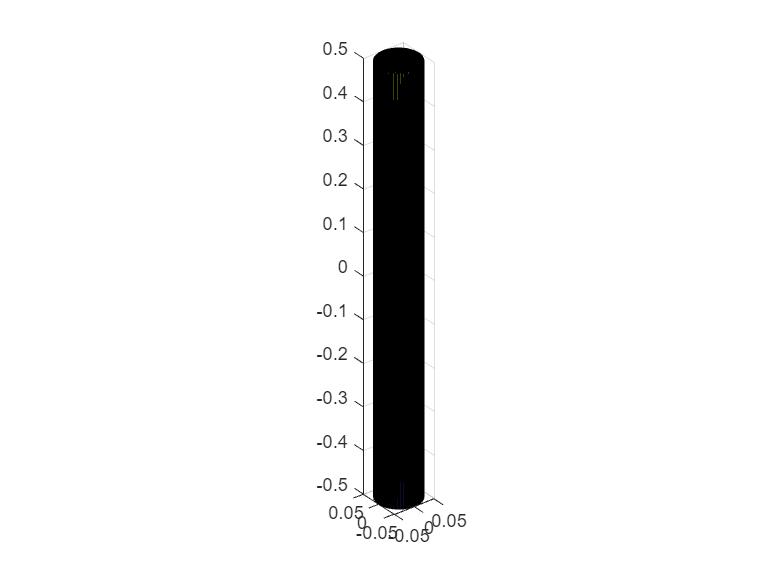

stlFile = 'Cylinder.stl';
figure
trisurf(stlread(stlFile))
axis equal

To represent the cylinder material properties, set these values for Young's modulus, Poisson's ratio, and mass density:

E = 70e9;     % Young's modulus in Pa
nu = 0.33;     % Poisson's ratio (nondimensional)
rho = 2700;    % Mass density in kg/m^3

## **Step 2: Specify the Locations of Interface Frames**

The cylinder has two interface frames where you can connect other Simscape™ Multibody™ elements, such as joints, constraints, forces, and sensors: one frame at each end of the cylinder.

The positions of all interface frame origins are specified in meters relative to same common reference frame used by the CAD geometry.

origins = [ 0      0      0.500      % top face of cylinder
            0      0     -0.500];    % bottom face of cylinder
numFrames = size(origins,1);

## **Step 3: Create the Finite-Element Mesh**

To generate the mesh for the cylinder, first call the [`createpde`](https://www.mathworks.com/help/releases/R2020b/pde/ug/createpde.html) function, which creates a structural model for modal analysis of a solid (3-D) problem. After importing the geometry and material properties of the cylinder, the [`generateMesh`](https://www.mathworks.com/help/releases/R2020b/pde/ug/pde.pdemodel.generatemesh.html?s_tid=doc_ta) function creates the mesh. You can control the accuracy of the mesh by modifying the `GeometricOrder`, `Hmax`, and `Hmin` properties below.

feModel = createpde('structural','modal-solid');
importGeometry(feModel,stlFile);
structuralProperties(feModel, ...
    'YoungsModulus',E, ...
    'PoissonsRatio',nu, ...
    'MassDensity',rho);
generateMesh(feModel, ...
    'GeometricOrder','linear', ...
    'Hmax',0.01, ...
    'Hmin',0.005);

## **Step 4: Set up the Multipoint Constraints for the Interface Frames**

Each interface frame on the block corresponds to a boundary node that contributes six degrees of freedom to the reduced-order model. There are several ways to ensure that the FEA substructuring method preserves the required degrees of freedom. For example, you can create a rigid constraint to connect the boundary node to a subset of finite-element nodes on the body. You can also use structural elements, such as beam or shell elements, to introduce nodes with six degrees of freedom.

This example uses a multipoint constraint (MPC) to preserve the six degrees of freedom at each boundary node. Note that a multipoint constraint is required if you plan on using the Reduced Order Flexible Solid block:

[https://www.mathworks.com/help/releases/R2020b/pde/ug/pde.structuralmodel.structuralbc.html#mw_93d97522-a469-41d0-a762-ed318bedbd79](https://www.mathworks.com/help/releases/R2020b/pde/ug/pde.structuralmodel.structuralbc.html#mw_93d97522-a469-41d0-a762-ed318bedbd79)

To identify the geometric regions (such as faces, edges, or vertices) to associate with each MPC, first plot the geometry by using the function [`pdegplot`](docid:pde_ug#bunex5a-1):

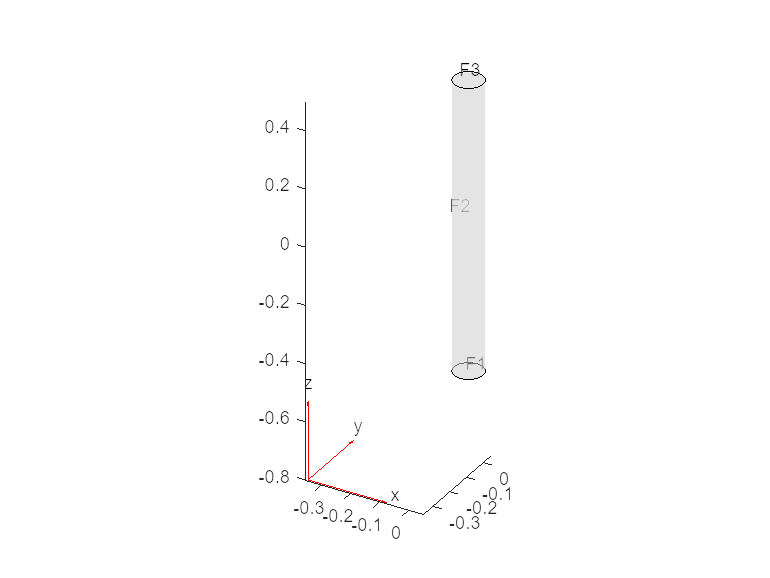

figure
pdegplot(feModel,'FaceLabels','on','FaceAlpha',0.5)

You can zoom, rotate, and pan this image to determine the labels for the faces corresponding to the boundary nodes. These faces define the MPCs associated with the boundary nodes in the cylinder:

- Bottom face of the cylinder: face 1

- Top face of the cylinder: face 3

**Note: The order of frames in **`faceIDs`** below must match the order of frames in **`origins`

faceIDs = [3,1];    % List in the same order as the interface frame origins

To verify these values, plot the mesh and highlight the selected faces:

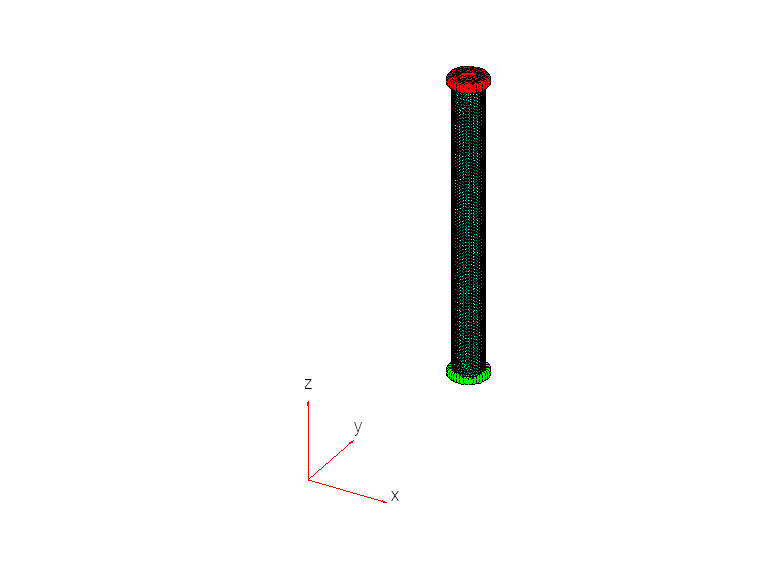

figure
pdemesh(feModel,'FaceAlpha',0.5)
hold on
colors = ['rgb' repmat('k',1,numFrames-3)];
assert(numel(faceIDs) == numFrames);
for k = 1:numFrames
    nodeIdxs = findNodes(feModel.Mesh,'region','Face',faceIDs(k));
    scatter3( ...
        feModel.Mesh.Nodes(1,nodeIdxs), ...
        feModel.Mesh.Nodes(2,nodeIdxs), ...
        feModel.Mesh.Nodes(3,nodeIdxs), ...
        'ok','MarkerFaceColor',colors(k))
    scatter3( ...
        origins(k,1), ...
        origins(k,2), ...
        origins(k,3), ...
        80,colors(k),'filled','s')
end
hold off

Call the function [`structuralBC`](https://www.mathworks.com/help/releases/R2020b/pde/ug/pde.structuralmodel.structuralbc.html?s_tid=doc_ta) to define the MPCs for the boundary nodes in these faces:

for k = 1:numFrames
    structuralBC(feModel, ...
        'Face',faceIDs(k), ...
        'Constraint','multipoint', ...
        'Reference',origins(k,:));
end

## **Step 5: Generate the Reduced-Order Model**

The function [`reduce`](https://www.mathworks.com/help/releases/R2020b/pde/ug/pde.structuralmodel.reduce.html?s_tid=doc_ta) applies the Craig-Bampton order reduction method and retains all fixed-interface modes up to a frequency of $10^4$ radians per second.

rom = reduce(feModel,'FrequencyRange',[0 1e4]);

Store the results of the reduction in a data structure cyl. Transpose the `ReferenceLocations` matrix to account for the different layout conventions used by Partial Differential Equation Toolbox and Simscape Multibody.

cyl.P = rom.ReferenceLocations';  % Interface frame locations (n x 3 matrix)
cyl.K = rom.K;                    % Reduced stiffness matrix
cyl.M = rom.M;                    % Reduced mass matrix

The boundary nodes in the reduced-order model must be specified in the same order as the corresponding interface frames on the block. This order is given by the rows of the array `origins`. If the order of the MPCs is different than the order specified by `origins`, permute the rows and columns of the various matrices so that they match the original order. This is an important step even if you are using your own FEA software. This will impact the ordering of your frames in the Reduced Order Flexible Solid block.

frmPerm = zeros(numFrames,1);    % Frame permutation vector
dofPerm = 1:size(cyl.K,1);       % DOF permutation vector

assert(size(cyl.P,1) == numFrames);
for i = 1:numFrames
    for j = 1:numFrames
        if isequal(cyl.P(j,:),origins(i,:))
            frmPerm(i) = j;
            dofPerm(6*(i-1)+(1:6)) = 6*(j-1)+(1:6);
            continue;
        end
    end
end
assert(numel(frmPerm) == numFrames);
assert(numel(dofPerm) == size(cyl.K,1));

cyl.P = cyl.P(frmPerm,:);
cyl.K = cyl.K(dofPerm,:);
cyl.K = cyl.K(:,dofPerm);
cyl.M = cyl.M(dofPerm,:);
cyl.M = cyl.M(:,dofPerm);

disp(cyl.P);

         0         0    0.5000
         0         0   -0.5000



disp(cyl.K);

   1.0e+08 *

  Columns 1 through 12

    0.0415    0.0000   -0.0000    0.0000   -0.0207   -0.0000   -0.0415   -0.0000    0.0000    0.0000   -0.0207    0.0000
    0.0000    0.0415   -0.0000    0.0207   -0.0000   -0.0000   -0.0000   -0.0415    0.0000    0.0207   -0.0000    0.0000
   -0.0000   -0.0000    5.5106   -0.0000   -0.0000    0.0000    0.0000    0.0000   -5.5106    0.0000    0.0000   -0.0000
    0.0000    0.0207   -0.0000    0.0139   -0.0000   -0.0000   -0.0000   -0.0207    0.0000    0.0069   -0.0000    0.0000
   -0.0207   -0.0000   -0.0000   -0.0000    0.0139    0.0000    0.0207    0.0000    0.0000   -0.0000    0.0069   -0.0000
   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0026    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0026
   -0.0415   -0.0000    0.0000   -0.0000    0.0207    0.0000    0.0415    0.0000   -0.0000   -0.0000    0.0207   -0.0000
   -0.0000   -0.0415    0.0000   -0.0207    0.0000    0.0000    0.0000    0.0415   -0.0000   -0.0207    0.0000   -0

disp(cyl.M);

  Columns 1 through 12

    7.8435   -0.0002    0.0012    0.0000   -1.1095   -0.0000    2.7021   -0.0002   -0.0011   -0.0001    0.6588    0.0000
   -0.0002    7.8440   -0.0010    1.1097   -0.0000    0.0000   -0.0003    2.7023    0.0009   -0.6588    0.0001   -0.0000
    0.0012   -0.0010    7.0595   -0.0002   -0.0002   -0.0000    0.0009   -0.0006    3.4871    0.0001    0.0002   -0.0000
    0.0000    1.1097   -0.0002    0.2046   -0.0000    0.0000   -0.0000    0.6587    0.0002   -0.1536    0.0000   -0.0000
   -1.1095   -0.0000   -0.0002   -0.0000    0.2045    0.0000   -0.6585    0.0000    0.0002    0.0000   -0.1536   -0.0000
   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0087    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0044
    2.7021   -0.0003    0.0009   -0.0000   -0.6585    0.0000    7.8455    0.0007   -0.0009   -0.0003    1.1103    0.0000
   -0.0002    2.7023   -0.0006    0.6587    0.0000    0.0000    0.0007    7.8445    0.0007   -1.1099    0.0003   -0.0000
   -0.00

## **Step 6: Check and Import Reduced-Order Data**

Now you can use the data structure cyl to set up the parameters of the Reduced Order Flexible Solid block. In the block, these parameters import the reduced-order data:

- **Origins**: cyl`.P`

- **Stiffness Matrix: cyl**`.K(1:24,1:24)`

- **Mass Matrix: cyl**`.M(1:24,1:24)`

optional: Check and make sure the data makes sense. For instance, there should be 6 generalized eigenvalues numerically zero

lambda = eig(cyl.K,cyl.M);
assert( all(abs(mink(lambda,6)) < 1e-3) )